syms z
X1 = 2*(z^-1)+4*(z^-2)+5*(z^-3)+3*(z^-4)+2*(z^-5);
iztrans(X1)

$$ans = 2\,\delta_{n-1,0}+4\,\delta_{n-2,0}+5\,\delta_{n-3,0}+3\,\delta_{n-4,0}+2\,\delta_{n-5,0}$$

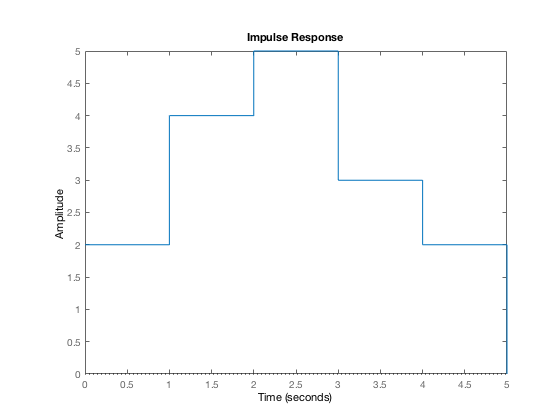


X1Z = X1 * (z^5);
iztrans(X1Z);

num = [2 4 5 3 2];
den = [1 0 0 0 0];
dimpulse(num,den,6);

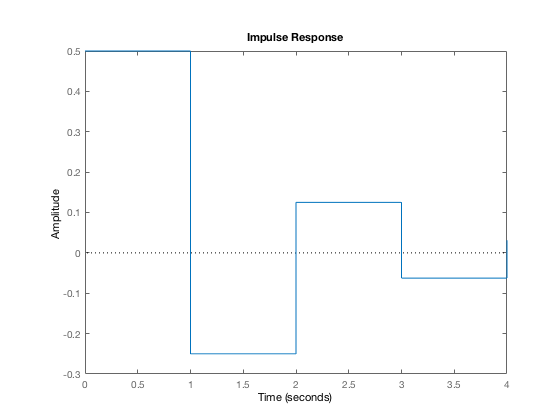


num1 = [1 -1 0];
den1 = [2 -1 -1];
dimpulse(num1,den1,5);

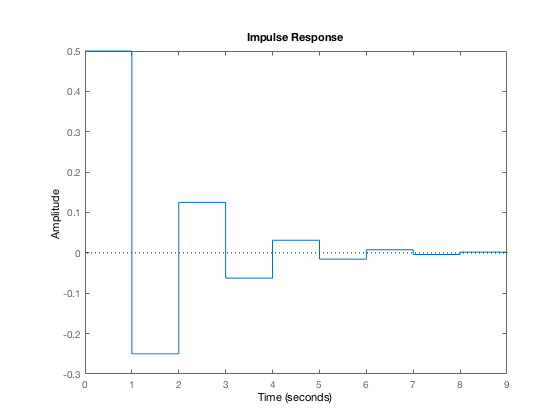

dimpulse(num1,den1,10);

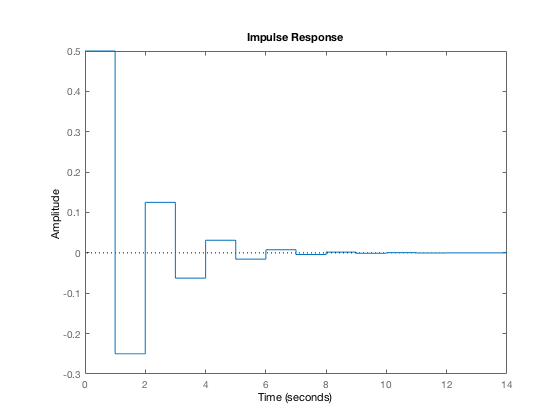

dimpulse(num1,den1,15);

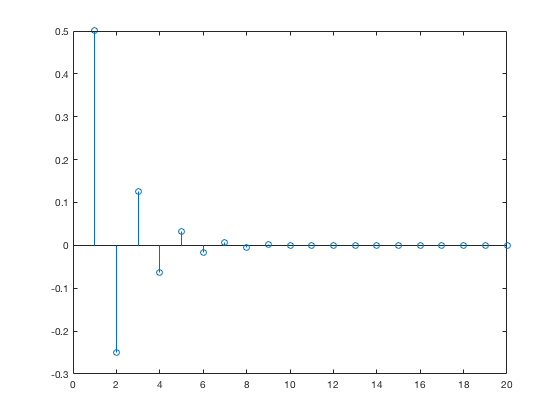

stem(dimpulse(num1,den1,20));


X2 = (1-(z^-1))/(2-(z^-1)-(z^-2))

$$X2 = \frac{\frac{1}{z}-1}{\frac{1}{z}+\frac{1}{z^{2}}-2}$$

iztrans(X2)

$$ans = \frac{{\left(-\frac{1}{2}\right)}^{n}}{2}$$

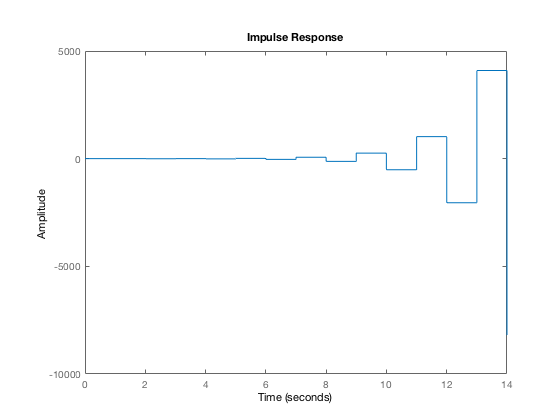


for n = 1:20
    x(n) = (-1/2)^(n-1)/2;
end

numX1 = [0 1];
denX1 = [1 2];
dimpulse(numX1, denX1,15);

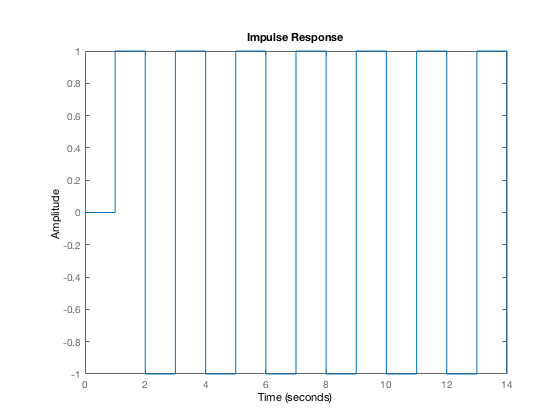

numX2 = [0 1];
denX2 = [1 1];
dimpulse(numX2, denX2,15);

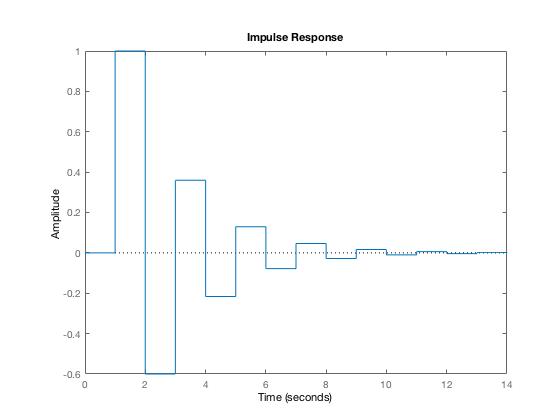

numX3 = [0 1];
denX3 = [1 0.6];
dimpulse(numX3, denX3,15);

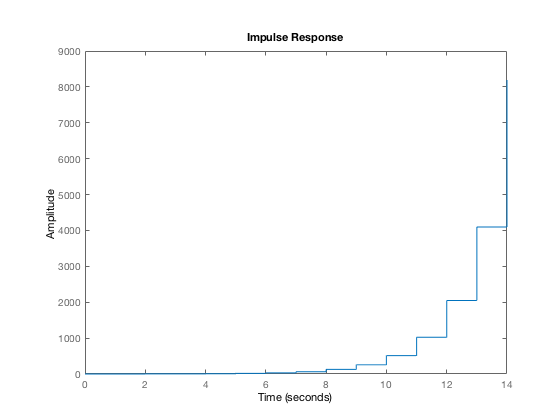

numX4 = [0 1];
denX4 = [1 -2];
dimpulse(numX4, denX4,15);

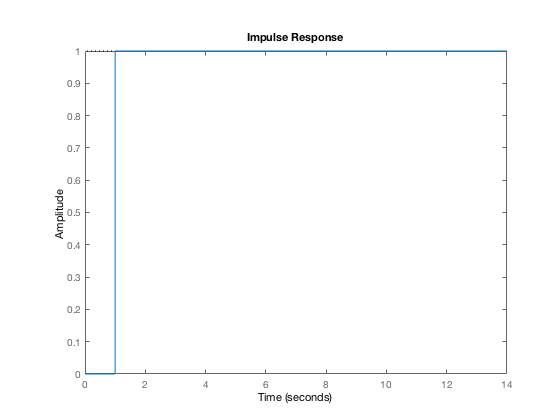

numX5 = [0 1];
denX5 = [1 -1];
dimpulse(numX5, denX5,15);

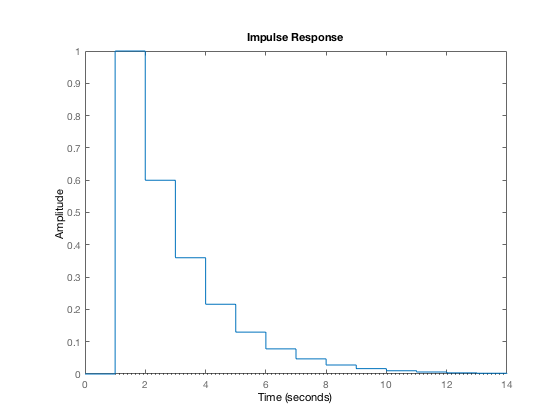

numX6 = [0 1];
denX6 = [1 -0.6];
dimpulse(numX6, denX6,15);

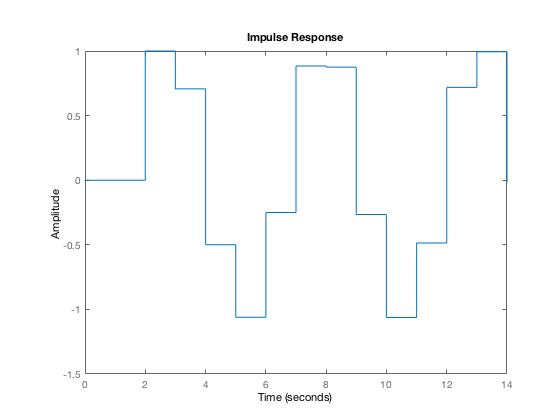

numX7 = [0 0 1];
denX7 = [1 -((1/sqrt(2))+ 1i*(1/sqrt(2))-1i*(1/sqrt(2))) 1];
dimpulse(numX7, denX7,15);

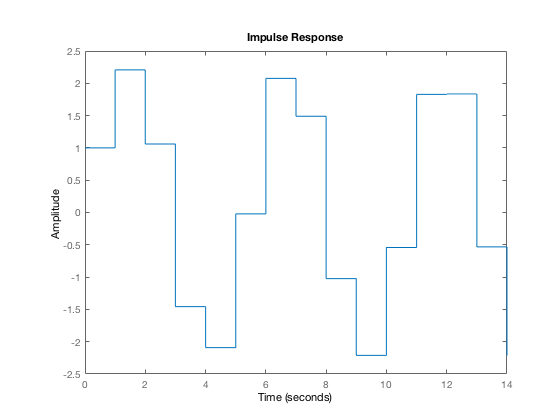

numX8 = [1 1.5 0.5];
denX8 = [1 -((1/sqrt(2))+ 1i*(1/sqrt(2))-1i*(1/sqrt(2))) 1];
dimpulse(numX8,denX8,15);

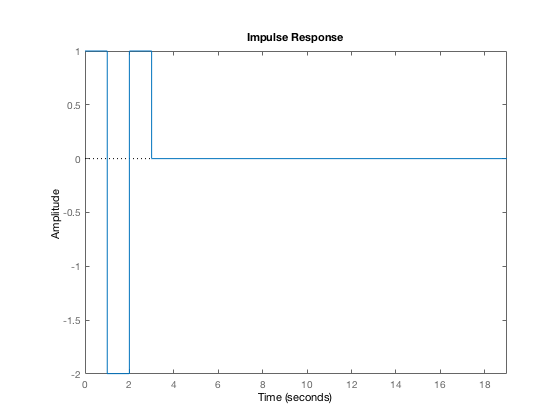

[x,fs] = audioread('mooncradle.wav');
soundsc(x,fs);
numS = [1 -2*cos(2*pi*200/fs) 1];
denS = [1 0 0];
dimpulse(numS, denS, 20);

y = conv(x,200);
soundsc(y,fs);